# FNN CNN LSTM - Get Data - for fast charge dataset



%여기까지 작업됨.
load ../B0006.mat
load ../B0007.mat

cap_gen_05_org = extract_discharge(B0005);
cap_gen_06_org = extract_discharge(B0006);
cap_gen_07_org = extract_discharge(B0007);


## Set index of each items of data

i=1;
capacityIdx                = i; i=i+1;                                                   
cycleTimeHourIdx           = i; i=i+1;                                        
restTimeHourIdx            = i; i=i+1;                                   
restCycleIdx               = i; i=i+1;                                
cTempMaxIdx                = i; i=i+1;                               
cCcEndTimeSecIdx           = i; i=i+1;                                    
dTempMaxIdx                = i; i=i+1;                               
dCcEndTimeSecIdx           = i; i=i+1;                                    
ohmIdx                     = i; i=i+1;                          
re_cIdx                    = i; i=i+1;                           
re_dIdx                    = i; i=i+1;                           
cycleNoChageReIdx          = i; i=i+1;                                     
cycleNoDischageReIdx       = i; i=i+1;                                        
pattern_dVoltIdx           = i; i=i+1;                                    
pattern_tempIdx            = i; i=i+1;                                   
pattern_CC_ampsIdx         = i; i=i+1;                                      
charVIT_Index              = i; i=i+1;   

pattern_dVolt_05_const       = 4.2 - 2.7 ; 
pattern_dVolt_06_const       = 4.2 - 2.5 ; 
pattern_dVolt_07_const       = 4.2 - 2.2 ; 
pattern_dVolt_consts = [pattern_dVolt_05_const pattern_dVolt_06_const pattern_dVolt_07_const ]; 

pattern_temp_05_const        = 24;
pattern_temp_06_const        = 24;
pattern_temp_07_const        = 24;

pattern_CC_amps_05_const     = 2;
pattern_CC_amps_06_const     = 2;
pattern_CC_amps_07_const     = 2;


## With Gen & Add 3 patterns  

data_gen_05 = extract_feature_all_v3(B0005,0,cap_gen_05_org);
data_gen_06 = extract_feature_all_v3(B0006,0,cap_gen_06_org);
data_gen_07 = extract_feature_all_v3(B0007,0,cap_gen_07_org);

%{
InitC_gen_05 					= 1.86; 
InitC_gen_06 					= 2.04;
InitC_gen_07 					= 1.89;
InitC_gen_0506 				    = 1.86;
InitC_gen_0605 				    = 2.04;
InitC_gen_05plus06 			    = 1.86;
InitC_gen_05plus07 			    = 1.86;
InitC_gen_06plus07 			    = 2.04;
InitC_gen_05plus06plus07 		= 1.86;    
%}

InitC_gen_05 					= data_gen_05(1,1); 
InitC_gen_06 					= data_gen_06(1,1); 
InitC_gen_07 					= data_gen_07(1,1); 

pattern_dVolt_vector   = ones(length(data_gen_05),1) *  pattern_dVolt_05_const; data_gen_05(:,pattern_dVoltIdx) = pattern_dVolt_vector;
pattern_dVolt_vector   = ones(length(data_gen_06),1) *  pattern_dVolt_06_const; data_gen_06(:,pattern_dVoltIdx) = pattern_dVolt_vector;
pattern_dVolt_vector   = ones(length(data_gen_07),1) *  pattern_dVolt_07_const; data_gen_07(:,pattern_dVoltIdx) = pattern_dVolt_vector;

pattern_temp_vector   = ones(length(data_gen_05),1) *  pattern_temp_05_const; data_gen_05(:,pattern_tempIdx) = pattern_temp_vector;
pattern_temp_vector   = ones(length(data_gen_06),1) *  pattern_temp_06_const; data_gen_06(:,pattern_tempIdx) = pattern_temp_vector;
pattern_temp_vector   = ones(length(data_gen_07),1) *  pattern_temp_07_const; data_gen_07(:,pattern_tempIdx) = pattern_temp_vector;

pattern_CC_amps_vector   = ones(length(data_gen_05),1) *  pattern_CC_amps_05_const; data_gen_05(:,pattern_CC_ampsIdx) = pattern_CC_amps_vector;
pattern_CC_amps_vector   = ones(length(data_gen_06),1) *  pattern_CC_amps_06_const; data_gen_06(:,pattern_CC_ampsIdx) = pattern_CC_amps_vector;
pattern_CC_amps_vector   = ones(length(data_gen_07),1) *  pattern_CC_amps_07_const; data_gen_07(:,pattern_CC_ampsIdx) = pattern_CC_amps_vector;

charVIT_gen_05 = data_gen_05(:, charVIT_Index:end);
charVIT_gen_06 = data_gen_06(:, charVIT_Index:end);
charVIT_gen_07 = data_gen_07(:, charVIT_Index:end);

cap_gen_05 = data_gen_05(:, 1);
cap_gen_06 = data_gen_06(:, 1);
cap_gen_07 = data_gen_07(:, 1);

[xB_gen_05, yB_gen_05, ym_gen_05, yr_gen_05] = minmax_norm(charVIT_gen_05, InitC_gen_05, cap_gen_05);
[xB_gen_06, yB_gen_06, ym_gen_06, yr_gen_06] = minmax_norm(charVIT_gen_06, InitC_gen_06, cap_gen_06);
[xB_gen_07, yB_gen_07, ym_gen_07, yr_gen_07] = minmax_norm(charVIT_gen_07, InitC_gen_07, cap_gen_07);


## remove rest cycle - suffix  => Nogen

## NoGen = generate new dataset 0506 0605 05plus06 05plus07 05plus06plus07

data_05 = data_gen_05;
data_06 = data_gen_06;
data_07 = data_gen_07;

restCycleTF_raw_index = find (data_07(:,restCycleIdx) == 1 )'; data_05(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (data_06(:,restCycleIdx) == 1 )'; data_06(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (data_07(:,restCycleIdx) == 1 )'; data_07(restCycleTF_raw_index,:)=[];

% ignore rest time , maxTempDt 
data_0506 = [ data_05(1:27,:) ; data_06(32:end,:) ]; % 30 -> 31
data_0605 = [ data_06(1:31,:) ; data_05(27:end,:) ];
data_0506_patten_change = [27 32];  % 1.6849 -> 1.6821
data_0605_patten_change = [31 27];  % 1.6976 -> 1.6849
  
data_05plus06       = [ data_05 ; data_06 ];
data_05plus07       = [ data_05 ; data_07 ];
data_06plus07       = [ data_06 ; data_07 ];
data_05plus06plus07 = [ data_05 ; data_06 ; data_07];

InitC_05                 = data_05( 1 , 1);
InitC_06                 = data_06( 1 , 1);
InitC_07                 = data_07( 1 , 1);
InitC_0506               = data_0506( 1 , 1);
InitC_0605               = data_0605( 1 , 1);
InitC_05plus06           = data_05plus06( 1 , 1);
InitC_05plus07           = data_05plus06( 1 , 1);
InitC_06plus07           = data_06plus07( 1 , 1);
InitC_05plus06plus07     = data_05plus06plus07( 1 , 1);

cap_05                 = data_05(:, 1);
cap_06                 = data_06(:, 1);
cap_07                 = data_07(:, 1);
cap_0506               = data_0506(:, 1);
cap_0605               = data_0605(:, 1);
cap_05plus06           = data_05plus06(:, 1);
cap_05plus07           = data_05plus06(:, 1);
cap_06plus07           = data_06plus07(:, 1);
cap_05plus06plus07     = data_05plus06plus07(:, 1);



charVIT_05                 = data_05(:, charVIT_Index:end);
charVIT_06                 = data_06(:, charVIT_Index:end);
charVIT_07                 = data_07(:, charVIT_Index:end);
charVIT_0506               = data_0506(:, charVIT_Index:end);
charVIT_0605               = data_0605(:, charVIT_Index:end);
charVIT_05plus06           = data_05plus06(:, charVIT_Index:end);
charVIT_05plus07           = data_05plus06(:, charVIT_Index:end);
charVIT_06plus07           = data_06plus07(:, charVIT_Index:end);
charVIT_05plus06plus07     = data_05plus06plus07(:, charVIT_Index:end);
charVIT_05plus06plus07_pattern = charVIT_05plus06plus07;




## 합칠 부분의 cap 값 검증

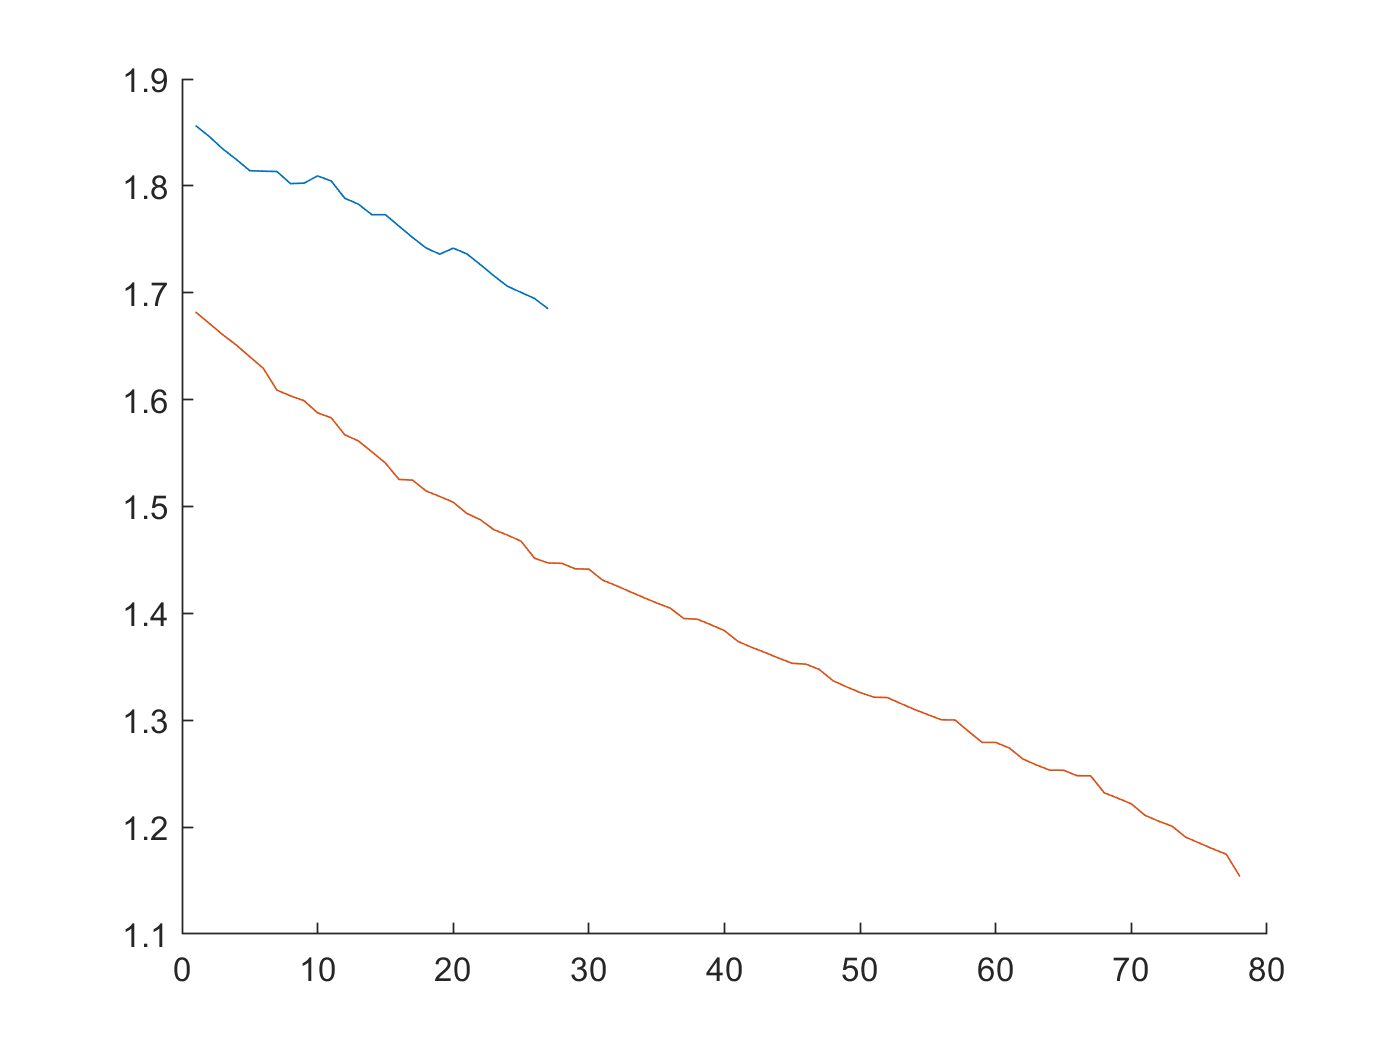

figure; hold on; plot(data_05(1:27,1)) ; plot(data_06(32:end,1)); hold off; 

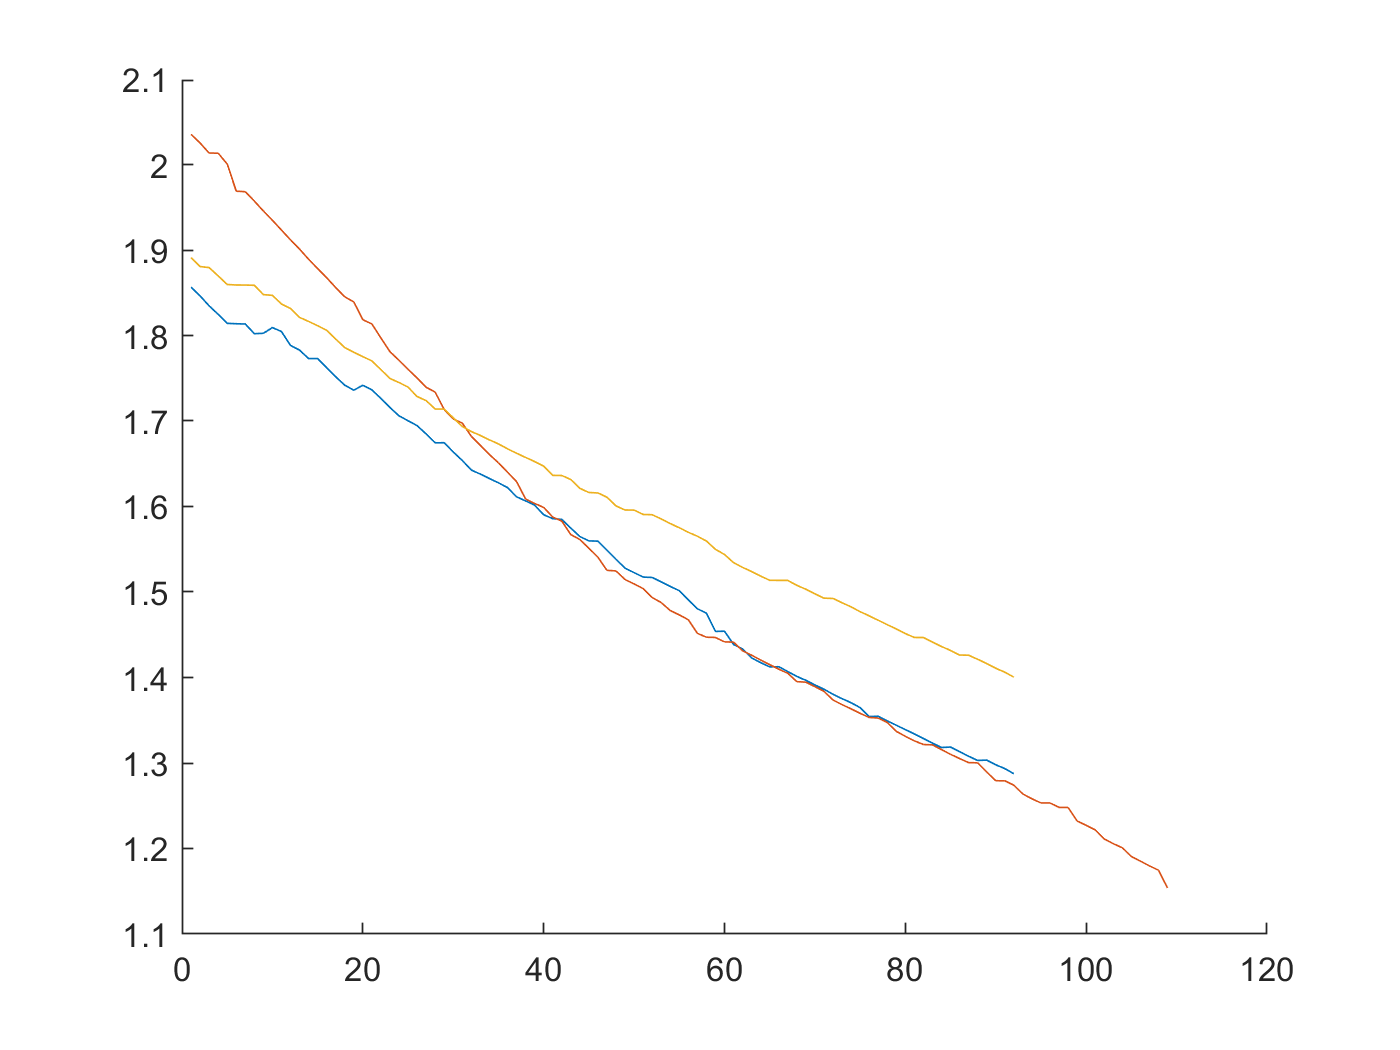

figure; hold on; plot(cap_05) ; plot(cap_06) ; plot(cap_07); hold off; 

% https://kr.mathworks.com/matlabcentral/answers/16439-finding-value-index-within-a-range
change_1v8_05 = find( cap_05 > 1.78 & cap_05 < 1.82 ) , cap_05(change_1v8_05) 

change_1v8_05 =      5
     6
     7
     8
     9
    10
    11
    12
    13


ans =     1.8142
    1.8138
    1.8134
    1.8021
    1.8026
    1.8093
    1.8046
    1.7884
    1.7829


change_1v8_06 = find( cap_06 > 1.78 & cap_06 < 1.82 ) , cap_06(change_1v8_06) 

change_1v8_06 =     20
    21
    22
    23


ans =     1.8185
    1.8135
    1.7971
    1.7810


change_1v8_07 = find( cap_07 > 1.78 & cap_07 < 1.82 ) , cap_07(change_1v8_07) 

change_1v8_07 =     14
    15
    16
    17
    18
    19


ans =     1.8165
    1.8114
    1.8061
    1.7958
    1.7859
    1.7803




change_1v7_05 = find( cap_05 > 1.68 & cap_05 < 1.72 ) , cap_05(change_1v7_05) 

change_1v7_05 =     23
    24
    25
    26
    27


ans =     1.7158
    1.7060
    1.7003
    1.6946
    1.6849


change_1v7_06 = find( cap_06 > 1.68 & cap_06 < 1.72 ) , cap_06(change_1v7_06) 

change_1v7_06 =     29
    30
    31
    32


ans =     1.7133
    1.7024
    1.6976
    1.6821


change_1v7_07 = find( cap_07 > 1.68 & cap_07 < 1.72 ) , cap_07(change_1v7_07) 

change_1v7_07 =     28
    29
    30
    31
    32
    33


ans =     1.7140
    1.7140
    1.7037
    1.6936
    1.6877
    1.6831



change_1v6_05 = find( cap_05 > 1.58 & cap_05 < 1.62 ) , cap_05(change_1v6_05) % 39 

change_1v6_05 =     37
    38
    39
    40
    41
    42


ans =     1.6113
    1.6066
    1.6015
    1.5904
    1.5858
    1.5849


change_1v6_06 = find( cap_06 > 1.58 & cap_06 < 1.62 ) , cap_06(change_1v6_06) % 40 39

change_1v6_06 =     38
    39
    40
    41
    42


ans =     1.6088
    1.6035
    1.5990
    1.5876
    1.5830


change_1v6_07 = find( cap_07 > 1.58 & cap_07 < 1.62 ) , cap_07(change_1v6_07) 

change_1v6_07 =     45
    46
    47
    48
    49
    50
    51
    52
    53


ans =     1.6164
    1.6158
    1.6109
    1.6007
    1.5959
    1.5958
    1.5907
    1.5904
    1.5854



change_1v5_05 = find( cap_05 > 1.48 & cap_05 < 1.52 ) , cap_05(change_1v5_05) 

change_1v5_05 =     51
    52
    53
    54
    55
    56
    57


ans =     1.5175
    1.5170
    1.5119
    1.5066
    1.5015
    1.4908
    1.4804


change_1v5_06 = find( cap_06 > 1.48 & cap_06 < 1.52 ) , cap_06(change_1v5_06) 

change_1v5_06 =     49
    50
    51
    52
    53


ans =     1.5145
    1.5094
    1.5040
    1.4935
    1.4876


change_1v5_07 = find( cap_07 > 1.48 & cap_07 < 1.52 ) , cap_07(change_1v5_07) 

change_1v5_07 =     64
    65
    66
    67
    68
    69
    70
    71
    72
    73


ans =     1.5187
    1.5136
    1.5136
    1.5136
    1.5078
    1.5032
    1.4978
    1.4928
    1.4924
    1.4875



change_1v4_05 = find( cap_05 > 1.38 & cap_05 < 1.42 ) , cap_05(change_1v4_05) 

change_1v4_05 =     64
    65
    66
    67
    68
    69
    70
    71
    72


ans =     1.4174
    1.4124
    1.4126
    1.4070
    1.4012
    1.3967
    1.3913
    1.3862
    1.3804


change_1v4_06 = find( cap_06 > 1.38 & cap_06 < 1.42 ) , cap_06(change_1v4_06) 

change_1v4_06 =     65
    66
    67
    68
    69
    70
    71


ans =     1.4150
    1.4097
    1.4049
    1.3952
    1.3945
    1.3893
    1.3838


change_1v4_07 = find( cap_07 > 1.38 & cap_07 < 1.42 ) , cap_07(change_1v4_07) 

change_1v4_07 =     89
    90
    91
    92


ans =     1.4163
    1.4108
    1.4062
    1.4005




data_05(26,1)

ans = 1.6946

data_05(27,1)

ans = 1.6849

data_05(28,1)

ans = 1.6745

data_06(28,1)

ans = 1.7338

data_06(29,1)

ans = 1.7133

data_06(30,1)

ans = 1.7024

data_06(31,1)

ans = 1.6976

data_06(32,1)

ans = 1.6821

charVIT_input_size                  = size(charVIT_05,2);
charVIT_05plus06_input_size         = size(charVIT_05plus06,2);
charVIT_05plus07_input_size         = size(charVIT_05plus07,2);
charVIT_06plus07_input_size         = size(charVIT_06plus07,2);
charVIT_05plus06plus07_input_size   = size(charVIT_05plus06plus07,2);



% 칼럼별로 연산
VIT_V_idx = [1:10];
VIT_I_idx = [11:20];
VIT_T_idx = [21:30];
VIT_step = length(VIT_V_idx);


%max(charVIT_05plus06plus07);
%max(charVIT_05plus06plus07(:,1));
%max(charVIT_05plus06plus07(:,2));

%charVIT_05plus06plus07(:,VIT_V_idx)
%max(charVIT_05plus06plus07(:,VIT_V_idx))
%min(charVIT_05plus06plus07(:,VIT_V_idx))
VIT_V_max  = max(max(charVIT_05plus06plus07(:,VIT_V_idx)))

VIT_V_max = 4.2131

VIT_V_min  = min(min(charVIT_05plus06plus07(:,VIT_V_idx)))

VIT_V_min = 3.6202

VIT_V_rate = max(max(charVIT_05plus06plus07(:,VIT_V_idx))) - min(min(charVIT_05plus06plus07(:,VIT_V_idx)))

VIT_V_rate = 0.5929


%charVIT_05plus06plus07(:,VIT_I_idx)
%max(charVIT_05plus06plus07(:,VIT_I_idx))
%min(charVIT_05plus06plus07(:,VIT_I_idx))
VIT_I_max  = max(max(charVIT_05plus06plus07(:,VIT_I_idx)))

VIT_I_max = 1.5141

VIT_I_min  = min(min(charVIT_05plus06plus07(:,VIT_I_idx)))

VIT_I_min = -0.0029

VIT_I_rate = max(max(charVIT_05plus06plus07(:,VIT_I_idx))) - min(min(charVIT_05plus06plus07(:,VIT_I_idx)))

VIT_I_rate = 1.5170



%charVIT_05plus06plus07(:,VIT_T_idx)
%max(charVIT_05plus06plus07(:,VIT_T_idx))
%min(charVIT_05plus06plus07(:,VIT_T_idx))
VIT_T_max  = max(max(charVIT_05plus06plus07(:,VIT_T_idx)))

VIT_T_max = 30.8301

VIT_T_min  = min(min(charVIT_05plus06plus07(:,VIT_T_idx)))

VIT_T_min = 23.0294

VIT_T_rate = max(max(charVIT_05plus06plus07(:,VIT_T_idx))) - min(min(charVIT_05plus06plus07(:,VIT_T_idx)))

VIT_T_rate = 7.8006



yCap = cap_05plus06plus07

yCap =     1.8565
    1.8463
    1.8346
    1.8248
    1.8142
    1.8138
    1.8134
    1.8021
    1.8026
    1.8093


size(yCap)

ans =    293     1


length(yCap)

ans = 293

cap_all = yCap

cap_all =     1.8565
    1.8463
    1.8346
    1.8248
    1.8142
    1.8138
    1.8134
    1.8021
    1.8026
    1.8093


cap_all_max = max(yCap)

cap_all_max = 2.0353

cap_all_min = min(yCap)

cap_all_min = 1.1538

cap_all_rate = cap_all_max / cap_all_min

cap_all_rate = 1.7640

yCap_result = ( yCap - cap_all_min ) / cap_all_rate

yCap_result =     0.3983
    0.3926
    0.3860
    0.3804
    0.3744
    0.3741
    0.3739
    0.3675
    0.3678
    0.3716




yPattern = data_05plus06plus07(:,pattern_dVoltIdx)

yPattern =     1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000


size(yPattern)

ans =    293     1


length(yPattern)

ans = 293

pattern_all = yPattern

pattern_all =     1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000


pattern_all_max = max(yPattern)

pattern_all_max = 2

pattern_all_min = min(yPattern)

pattern_all_min = 1.5000

pattern_all_rate = pattern_all_max / pattern_all_min

pattern_all_rate = 1.3333

yPattern_result = ( yPattern - pattern_all_min ) / pattern_all_rate

yPattern_result =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




[yCap_05, yPattern_05, x_05] = minmax_norm_v2(charVIT_05,cap_05,data_05(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_06, yPattern_06, x_06] = minmax_norm_v2(charVIT_06,cap_06,data_06(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_07, yPattern_07, x_07] = minmax_norm_v2(charVIT_07,cap_07,data_07(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_0506, yPattern_0506, x_0506] = minmax_norm_v2(charVIT_0506,cap_0506,data_0506(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_0605, yPattern_0605, x_0605] = minmax_norm_v2(charVIT_0605,cap_0605,data_0605(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_05plus06, yPattern_05plus06, x_05plus06] = minmax_norm_v2(charVIT_05plus06,cap_05plus06,data_05plus06(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_05plus07, yPattern_05plus07, x_05plus07] = minmax_norm_v2(charVIT_05plus07,cap_05plus07,data_05plus07(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_06plus07, yPattern_06plus07, x_06plus07] = minmax_norm_v2(charVIT_06plus07,cap_06plus07,data_06plus07(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
[yCap_05plus06plus07, yPattern_05plus06plus07, x_05plus06plus07] = minmax_norm_v2(charVIT_05plus06plus07,cap_05plus06plus07,data_05plus06plus07(:,pattern_dVoltIdx),VIT_step,VIT_V_min,VIT_I_min,VIT_T_min,VIT_V_rate,VIT_I_rate,VIT_T_rate,cap_all_min,cap_all_rate,pattern_all_min,pattern_all_rate );
x_05plus06plus07_pattern = x_05plus06plus07 ;




idx_0506           = data_0506_patten_change(1)+1;
idx_0506_change    = data_0506_patten_change(1)+1;
x_0506_change        = x_0506(idx_0506_change:end,:);
yCap_0506_change        = yCap_0506(idx_0506_change:end);
yCap_0506_change_before    = nan(1,idx_0506_change-1);
yPattern_0506_change        = yPattern_0506(idx_0506_change:end);
yPattern_0506_change_before    = nan(1,idx_0506_change-1);

idx_0605           = data_0605_patten_change(1)+1;
idx_0605_change    = data_0605_patten_change(1)+1;
x_0605_change        = x_0605(idx_0605:end,:);
yCap_0605_change        = yCap_0605(idx_0605:end);
yCap_0605_change_before    = nan(1,idx_0605-1);
yPattern_0605_change        = yPattern_0605(idx_0605:end);
yPattern_0605_change_before    = nan(1,idx_0605-1);



## For Linear Regression & Arima

regression_vector_05 = [ ...
    data_05(:, cCcEndTimeSecIdx ) ...
    data_05(:, pattern_CC_ampsIdx ) ...
    data_05(:, capacityIdx ) ] ;

regression_vector_06 = [ ...
    data_06(:, cCcEndTimeSecIdx ) ...
    data_06(:, pattern_dVoltIdx ) ...
    data_06(:, capacityIdx ) ] ;

regression_vector_07 = [ ...
    data_07(:, cCcEndTimeSecIdx ) ...
    data_07(:, pattern_dVoltIdx ) ...
    data_07(:, capacityIdx ) ] ;

regression_vector_0506 = [ ...
    data_0506(:, cCcEndTimeSecIdx ) ...
    data_0506(:, pattern_dVoltIdx ) ...
    data_0506(:, capacityIdx ) ] ;

regression_vector_0605 = [ ...
    data_0605(:, cCcEndTimeSecIdx ) ...
    data_0605(:, pattern_dVoltIdx ) ...
    data_0605(:, capacityIdx ) ] ;

regression_vector_05plus06 = [ ...
    data_05plus06(:, cCcEndTimeSecIdx ) ...
    data_05plus06(:, pattern_dVoltIdx ) ...
    data_05plus06(:, capacityIdx ) ] ;

regression_vector_05plus06plus07 = [ ...
    data_05plus06plus07(:, cCcEndTimeSecIdx ) ...
    data_05plus06plus07(:, pattern_dVoltIdx ) ...
    data_05plus06plus07(:, capacityIdx ) ] ;

regression_table_05 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_07 = array2table(regression_vector_07,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_0506 = array2table(regression_vector_0506,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_0605 = array2table(regression_vector_0605,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05plus06 = array2table(regression_vector_05plus06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05plus06plus07 = array2table(regression_vector_05plus06plus07,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

xCcTimeSec_05       = regression_vector_05(:,1);
xCcTimeHour_05      = xCcTimeSec_05./1200 ; % sec to hour
xPattern_05         = regression_vector_05(:,2);
xCcTimeSec_06       = regression_vector_06(:,1);
xCcTimeHour_06      = xCcTimeSec_06./1200 ; % sec to hour
xPattern_06         = regression_vector_06(:,2);
xCcTimeSec_0506     = regression_vector_0506(:,1);
xCcTimeHour_0506    = xCcTimeSec_0506./1200 ; % sec to hour
xPattern_0506       = regression_vector_0506(:,2);
xCcTimeSec_0605     = regression_vector_0605(:,1);
xCcTimeHour_0605    = xCcTimeSec_0605./1200 ; % sec to hour
xPattern_0605       = regression_vector_0605(:,2);

cap_0506_change                  = cap_0506(idx_0506_change:end);
cap_0506_change_before           = nan(1,idx_0506_change-1);
xPattern_0506_change             = xPattern_0506(idx_0506_change:end);
xPattern_0506_change_before      = nan(1,idx_0506_change-1);
cap_0605_change                  = cap_0605(idx_0605:end);
cap_0605_change_before           = nan(1,idx_0605-1);
xPattern_0605_change             = xPattern_0605(idx_0605:end);
xPattern_0605_change_before      = nan(1,idx_0605-1);



ryan_gen_data_desc = 'battery data';
save('ryan_gen_data.mat','ryan_gen_data_desc');

save('ryan_gen_data.mat',  'cap_gen_05_org' ,'-append')
save('ryan_gen_data.mat',  'cap_gen_06_org' ,'-append')
save('ryan_gen_data.mat',  'cap_gen_07_org' ,'-append')
save('ryan_gen_data.mat',  'data_gen_05'                         ,'-append')
save('ryan_gen_data.mat',  'data_gen_06'                         ,'-append')
save('ryan_gen_data.mat',  'data_gen_07'                         ,'-append')
save('ryan_gen_data.mat',  'charVIT_gen_05'                      ,'-append')
save('ryan_gen_data.mat',  'charVIT_gen_06'                      ,'-append')
save('ryan_gen_data.mat',  'charVIT_gen_07'                      ,'-append')
save('ryan_gen_data.mat',  'cap_gen_05'                          ,'-append')
save('ryan_gen_data.mat',  'cap_gen_06'                          ,'-append')
save('ryan_gen_data.mat',  'cap_gen_07'                          ,'-append')
save('ryan_gen_data.mat',  'xB_gen_05' , 'yB_gen_05' , 'ym_gen_05' , 'yr_gen_05'  ,'-append')
save('ryan_gen_data.mat',  'xB_gen_06' , 'yB_gen_06' , 'ym_gen_06' , 'yr_gen_06'  ,'-append')
save('ryan_gen_data.mat',  'xB_gen_07' , 'yB_gen_07' , 'ym_gen_07' , 'yr_gen_07'  ,'-append')
save('ryan_gen_data.mat',  'data_05'                             ,'-append')       
save('ryan_gen_data.mat',  'data_06'                             ,'-append')
save('ryan_gen_data.mat',  'data_07'                             ,'-append')
save('ryan_gen_data.mat',  'data_0506'                           ,'-append')
save('ryan_gen_data.mat',  'data_0605'                           ,'-append')
save('ryan_gen_data.mat',  'data_05plus06'                       ,'-append')
save('ryan_gen_data.mat',  'data_05plus07'                       ,'-append')
save('ryan_gen_data.mat',  'data_06plus07'                       ,'-append')
save('ryan_gen_data.mat',  'data_05plus06plus07'                 ,'-append')
save('ryan_gen_data.mat',  'data_0506_patten_change'             ,'-append')
save('ryan_gen_data.mat',  'data_0605_patten_change'             ,'-append')   
save('ryan_gen_data.mat',  'InitC_05' 			                 ,'-append')  	
save('ryan_gen_data.mat',  'InitC_06' 				             ,'-append')  
save('ryan_gen_data.mat',  'InitC_07' 				             ,'-append')  
save('ryan_gen_data.mat',  'InitC_0506' 			             ,'-append')  
save('ryan_gen_data.mat',  'InitC_0605' 			             ,'-append')  
save('ryan_gen_data.mat',  'InitC_05plus06' 		             ,'-append')  
save('ryan_gen_data.mat',  'InitC_05plus07' 		             ,'-append')  
save('ryan_gen_data.mat',  'InitC_06plus07' 		             ,'-append')  
save('ryan_gen_data.mat',  'InitC_05plus06plus07'                ,'-append')  
save('ryan_gen_data.mat',  'cap_05'                              ,'-append') 
save('ryan_gen_data.mat',  'cap_06'                              ,'-append') 
save('ryan_gen_data.mat',  'cap_07'                              ,'-append') 
save('ryan_gen_data.mat',  'cap_0506'                            ,'-append') 
save('ryan_gen_data.mat',  'cap_0605'                            ,'-append') 
save('ryan_gen_data.mat',  'cap_05plus06'                        ,'-append') 
save('ryan_gen_data.mat',  'cap_05plus07'                        ,'-append') 
save('ryan_gen_data.mat',  'cap_06plus07'                        ,'-append') 
save('ryan_gen_data.mat',  'cap_05plus06plus07'                  ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05'                          ,'-append') 
save('ryan_gen_data.mat',  'charVIT_06'                          ,'-append') 
save('ryan_gen_data.mat',  'charVIT_07'                          ,'-append') 
save('ryan_gen_data.mat',  'charVIT_0506'                        ,'-append') 
save('ryan_gen_data.mat',  'charVIT_0605'                        ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus06'                    ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus07'                    ,'-append') 
save('ryan_gen_data.mat',  'charVIT_06plus07'                    ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus06plus07'              ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus06plus07_pattern'      ,'-append') 
save('ryan_gen_data.mat',  'charVIT_input_size'                  ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus06_input_size'         ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus07_input_size'         ,'-append') 
save('ryan_gen_data.mat',  'charVIT_06plus07_input_size'         ,'-append') 
save('ryan_gen_data.mat',  'charVIT_05plus06plus07_input_size'   ,'-append') 
save('ryan_gen_data.mat',  'VIT_V_max'                           ,'-append')
save('ryan_gen_data.mat',  'VIT_V_min'                           ,'-append')
save('ryan_gen_data.mat',  'VIT_V_rate'                          ,'-append')
save('ryan_gen_data.mat',  'VIT_I_max'                           ,'-append') 
save('ryan_gen_data.mat',  'VIT_I_min'                           ,'-append') 
save('ryan_gen_data.mat',  'VIT_I_rate'                          ,'-append') 
save('ryan_gen_data.mat',  'VIT_T_max'                           ,'-append') 
save('ryan_gen_data.mat',  'VIT_T_min'                           ,'-append') 
save('ryan_gen_data.mat',  'VIT_T_rate'                          ,'-append') 
save('ryan_gen_data.mat',  'capacityIdx'                         ,'-append')                 
save('ryan_gen_data.mat',  'cycleTimeHourIdx'                    ,'-append') 
save('ryan_gen_data.mat',  'restTimeHourIdx'                     ,'-append') 
save('ryan_gen_data.mat',  'restCycleIdx'                        ,'-append') 
save('ryan_gen_data.mat',  'cTempMaxIdx'                         ,'-append') 
save('ryan_gen_data.mat',  'cCcEndTimeSecIdx'                    ,'-append') 
save('ryan_gen_data.mat',  'dTempMaxIdx'                         ,'-append') 
save('ryan_gen_data.mat',  'dCcEndTimeSecIdx'                    ,'-append') 
save('ryan_gen_data.mat',  'ohmIdx'                              ,'-append') 
save('ryan_gen_data.mat',  're_cIdx'                             ,'-append') 
save('ryan_gen_data.mat',  're_dIdx'                             ,'-append') 
save('ryan_gen_data.mat',  'cycleNoChageReIdx'                   ,'-append') 
save('ryan_gen_data.mat',  'cycleNoDischageReIdx'                ,'-append') 
save('ryan_gen_data.mat',  'pattern_dVoltIdx'                    ,'-append') 
save('ryan_gen_data.mat',  'pattern_tempIdx'                     ,'-append') 
save('ryan_gen_data.mat',  'pattern_CC_ampsIdx'                  ,'-append') 
save('ryan_gen_data.mat',  'charVIT_Index'                       ,'-append')    
save('ryan_gen_data.mat',  'pattern_dVolt_05_const'              ,'-append')
save('ryan_gen_data.mat',  'pattern_dVolt_06_const'              ,'-append')
save('ryan_gen_data.mat',  'pattern_dVolt_07_const'              ,'-append')
save('ryan_gen_data.mat',  'pattern_dVolt_consts'                ,'-append')
save('ryan_gen_data.mat',  'pattern_CC_amps_05_const'            ,'-append')  
save('ryan_gen_data.mat',  'pattern_CC_amps_06_const'            ,'-append') 
save('ryan_gen_data.mat',  'pattern_CC_amps_07_const'            ,'-append')
save('ryan_gen_data.mat',  'pattern_temp_05_const'               ,'-append')   
save('ryan_gen_data.mat',  'pattern_temp_06_const'               ,'-append')   
save('ryan_gen_data.mat',  'pattern_temp_07_const'               ,'-append')
save('ryan_gen_data.mat',  'pattern_all_max'               ,'-append')                           
save('ryan_gen_data.mat',  'pattern_all_min'               ,'-append')
save('ryan_gen_data.mat',  'pattern_all_rate'              ,'-append')
save('ryan_gen_data.mat',  'cap_all_max'                   ,'-append')
save('ryan_gen_data.mat',  'cap_all_min'                   ,'-append')
save('ryan_gen_data.mat',  'cap_all_rate'                  ,'-append')
save('ryan_gen_data.mat',  'cap_all_max'                   ,'-append')
save('ryan_gen_data.mat',  'cap_all_min'                   ,'-append')
save('ryan_gen_data.mat',  'cap_all_rate'                  ,'-append')
save('ryan_gen_data.mat',  'yCap_05'                       ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_06'                       ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_07'                       ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_0506'                     ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_0605'                     ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_05plus06'                 ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_05plus07'                 ,'-append')                                                                  
save('ryan_gen_data.mat',  'yCap_06plus07'                 ,'-append')                                                                             
save('ryan_gen_data.mat',  'yCap_05plus06plus07'           ,'-append')                                                                         
save('ryan_gen_data.mat',  'yPattern_05'                   ,'-append')
save('ryan_gen_data.mat',  'yPattern_06'                   ,'-append')
save('ryan_gen_data.mat',  'yPattern_07'                   ,'-append')
save('ryan_gen_data.mat',  'yPattern_0506'                 ,'-append')
save('ryan_gen_data.mat',  'yPattern_0605'                 ,'-append')
save('ryan_gen_data.mat',  'yPattern_05plus06'             ,'-append')
save('ryan_gen_data.mat',  'yPattern_05plus07'             ,'-append')
save('ryan_gen_data.mat',  'yPattern_06plus07'             ,'-append')
save('ryan_gen_data.mat',  'yPattern_05plus06plus07'       ,'-append')
save('ryan_gen_data.mat',  'x_05'                          ,'-append')
save('ryan_gen_data.mat',  'x_06'                          ,'-append')
save('ryan_gen_data.mat',  'x_07'                          ,'-append')
save('ryan_gen_data.mat',  'x_0506'                        ,'-append')
save('ryan_gen_data.mat',  'x_0605'                        ,'-append')
save('ryan_gen_data.mat',  'x_05plus06'                    ,'-append')
save('ryan_gen_data.mat',  'x_05plus07'                    ,'-append')
save('ryan_gen_data.mat',  'x_06plus07'                    ,'-append')
save('ryan_gen_data.mat',  'x_05plus06plus07'              ,'-append')
save('ryan_gen_data.mat',  'x_05plus06plus07_pattern'      ,'-append')
save('ryan_gen_data.mat',  'idx_0506'                      ,'-append')
save('ryan_gen_data.mat',  'idx_0506_change'               ,'-append')
save('ryan_gen_data.mat',  'x_0506_change'                 ,'-append')
save('ryan_gen_data.mat',  'yCap_0506_change'              ,'-append')
save('ryan_gen_data.mat',  'yCap_0506_change_before'       ,'-append')
save('ryan_gen_data.mat',  'yPattern_0506_change'          ,'-append')
save('ryan_gen_data.mat',  'yPattern_0506_change_before'   ,'-append')
save('ryan_gen_data.mat',  'idx_0605'                      ,'-append')
save('ryan_gen_data.mat',  'idx_0605_change'               ,'-append')
save('ryan_gen_data.mat',  'x_0605_change'                 ,'-append')
save('ryan_gen_data.mat',  'yCap_0605_change'              ,'-append')
save('ryan_gen_data.mat',  'yCap_0605_change_before'       ,'-append')
save('ryan_gen_data.mat',  'yPattern_0605_change'          ,'-append')
save('ryan_gen_data.mat',  'yPattern_0605_change_before'   ,'-append')   

save('ryan_gen_data.mat',  'regression_vector_05' ,  'regression_vector_06' ,  'regression_vector_07' ,  'regression_vector_0506' ,  'regression_vector_0605' ,  'regression_vector_05plus06' ,  'regression_vector_05plus06plus07', '-append')  
save('ryan_gen_data.mat',  'regression_table_05' ,  'regression_table_06' ,  'regression_table_07' ,  'regression_table_0506' ,  'regression_table_0605' ,  'regression_table_05plus06' ,  'regression_table_05plus06plus07', '-append')  

save('ryan_gen_data.mat',  'xCcTimeSec_05'                 ,'-append')
save('ryan_gen_data.mat',  'xCcTimeHour_05'                ,'-append')
save('ryan_gen_data.mat',  'xPattern_05'                   ,'-append')
save('ryan_gen_data.mat',  'xCcTimeSec_06'                 ,'-append')
save('ryan_gen_data.mat',  'xCcTimeHour_06'                ,'-append')
save('ryan_gen_data.mat',  'xPattern_06'                   ,'-append')
save('ryan_gen_data.mat',  'xCcTimeSec_0506'               ,'-append')
save('ryan_gen_data.mat',  'xCcTimeHour_0506'              ,'-append')
save('ryan_gen_data.mat',  'xPattern_0506'                 ,'-append')
save('ryan_gen_data.mat',  'xCcTimeSec_0605'               ,'-append')
save('ryan_gen_data.mat',  'xCcTimeHour_0605'              ,'-append')
save('ryan_gen_data.mat',  'xPattern_0605'                 ,'-append')
save('ryan_gen_data.mat',  'cap_0506_change'               ,'-append')
save('ryan_gen_data.mat',  'cap_0506_change_before'        ,'-append')
save('ryan_gen_data.mat',  'xPattern_0506_change'          ,'-append')
save('ryan_gen_data.mat',  'xPattern_0506_change_before'   ,'-append')
save('ryan_gen_data.mat',  'cap_0605_change'               ,'-append')
save('ryan_gen_data.mat',  'cap_0605_change_before'        ,'-append')
save('ryan_gen_data.mat',  'xPattern_0605_change'          ,'-append')
save('ryan_gen_data.mat',  'xPattern_0605_change_before'   ,'-append')

